%Mechatronics Homework 1.
%Grounded Joints:ADG




%Joint Coordinates

A = [1.4 0.485 0]

A =     1.4000    0.4850         0


B = [1.67 .99 0]

B =     1.6700    0.9900         0


C = [.255 1.035 0]

C =     0.2550    1.0350         0


D = [.285 .055 0]

D =     0.2850    0.0550         0


E = [.195 2.54 0]

E =     0.1950    2.5400         0


F = [-.98 2.57 0]

F =    -0.9800    2.5700         0


G = [.05 .2 0]

G =     0.0500    0.2000         0




%Point masses
artifactweight = 200

artifactweight = 200

artifactmass = 200/9.81

artifactmass = 20.3874


%Link Lengths

% Define link lengths based on the coordinates
lengthAB = .5726

lengthAB = 0.5726

lengthBC = 1.4157

lengthBC = 1.4157

lengthCD = norm(D-C)

lengthCD = 0.9805

lengthEC = norm(E-C)

lengthEC = 1.5062

lengthDE = 2.4866

lengthDE = 2.4866

lengthEF = 1.1754

lengthEF = 1.1754

lengthGF = 2.5841

lengthGF = 2.5841

lengthGGripper = lengthGF + 1.843

lengthGGripper = 4.4271

%Calculating gripper joint coordinates:

thetaGF = atan((F(2)-G(2))/(F(1)-G(1)))

thetaGF = -1.1608

Grip = [(-cos(thetaGF)*lengthGGripper+G(1)) (-sin(thetaGF)*lengthGGripper+G(2)) 0]

Grip =    -1.7146    4.2602         0


lengthFGripper = norm(Grip-F);


width = .10

width = 0.1000

thickness = .05

thickness = 0.0500

jointdiameter = .06

jointdiameter = 0.0600

density = 2000;

% Define link masses
massAB = lengthAB*width*thickness*density

massAB = 5.7260

massBC = lengthBC*width*thickness*density

massBC = 14.1570

massDE = lengthDE*width*thickness*density

massDE = 24.8660

massEF = lengthEF*width*thickness*density

massEF = 11.7540

massGF = (lengthGGripper)*width*thickness*density

massGF = 44.2710

massGGrip = (lengthGGripper)*width*thickness*density +artifactmass

massGGrip = 64.6584


%Define link weights
WAB = [0 -massAB*9.81 0]

WAB =          0  -56.1721         0


WBC = [0 -massBC*9.81 0]

WBC =          0 -138.8802         0


WDE = [0 -massDE*9.81 0]

WDE =          0 -243.9355         0


WEF = [0 -massEF*9.81 0]

WEF =          0 -115.3067         0


WGF = [0 -massGF*9.81 0]

WGF =          0 -434.2985         0


WGGrip = [0 -massGGrip*9.81 0]

WGGrip =          0 -634.2985         0




%Center of mass of each link
S1 = (A+B)/2;
S2 = (B+C)/2;
S3 = (D+E)/2;
S4 = (F+E)/2;
S5minusartifact = (G+Grip)/2;
S5 = (artifactmass*Grip + S5minusartifact*massGF)/(massGGrip);
lengthS5Gripper = norm(S5-Grip);



%Calculate forces and torque based on static equilibrium conditions
syms FAx FAy FBx FBy FCx FCy FDx FDy FEx FEy FFx FFy FGx FGy Tin

ForceA = [FAx FAy 0];
ForceB = [FBx FBy 0];
ForceC = [FCx FCy 0];
ForceD = [FDx FDy 0];
ForceE = [FEx FEy 0];
ForceF = [FFx FFy 0];
ForceG = [FGx FGy 0];
InputTorque = [0 0 Tin];

ForceFromArtifact = [0 -200 0];

%Forces
%ForceAB
eqn1 = ForceA + ForceB + WAB == 0;
%ForceBC
eqn2 = -ForceB + ForceC + WBC == 0;
%ForceCDE
eqn3 = -ForceC + ForceD + ForceE + WDE == 0;
%ForceEF
eqn4 = -ForceE + ForceF + WEF == 0;
%ForceGGrip
eqn5 = WGGrip + ForceG + -ForceF == 0;

%Moments
%MomentAB
eqn6 = InputTorque + cross(A-S1,ForceA) + cross(B-S1,ForceB) == 0;
%MomentBC
eqn7 = cross(C-S2, ForceC) + cross(B-S2,-ForceB) == 0;
%MomentCDE
eqn8 = cross(C-S3, -ForceC) + cross(D-S3, ForceD) + cross(E-S3, ForceE) == 0;
%MomentEF
eqn9 = cross(E-S4, -ForceE) + cross(F-S4, ForceF) == 0;
%MomentGGrip
eqn10 = cross(G-S5, ForceG) + cross(F-S5, -ForceF) == 0;

eqnmatrix = [eqn1, eqn2, eqn3, eqn4, eqn5, eqn6, eqn7, eqn8, eqn9, eqn10,];
% Solve the system of equations for the unknown forces and torque
staticsolution = solve(eqnmatrix, [FAx, FAy, FBx, FBy, FCx, FCy, FDx, FDy, FEx, FEy, FFx, FFy, FGx, FGy, Tin]);

vectorForceA = [double(staticsolution.FAx) double(staticsolution.FAy) 0]

vectorForceA =   879.3261   97.6477         0


vectorForceB = [double(staticsolution.FBx) double(staticsolution.FBy) 0]

vectorForceB =  -879.3261  -41.4757         0


vectorForceC = [double(staticsolution.FCx) double(staticsolution.FCy) 0]

vectorForceC =  -879.3261   97.4045         0


vectorForceD = [double(staticsolution.FDx) double(staticsolution.FDy) 0]

vectorForceD =  -539.9170  390.3276         0


vectorForceE = [double(staticsolution.FEx) double(staticsolution.FEy) 0]

vectorForceE =  -339.4090  -48.9876         0


vectorForceF = [double(staticsolution.FFx) double(staticsolution.FFy) 0]

vectorForceF =  -339.4090   66.3191         0


vectorForceG = [double(staticsolution.FGx) double(staticsolution.FGy) 0]

vectorForceG =  -339.4090  700.6176         0


vectorTorquein = [0 0 double(staticsolution.Tin)]

vectorTorquein =          0         0 -425.2780






%Newton's II law
%Angular velocity and angular acceleration?
%Calculating instantaneous angular velocity under assumptions.
omegaGF_RPM = -23.148

omegaGF_RPM = -23.1480

omegaGF = omegaGF_RPM*(2*pi/60)

omegaGF = -2.4241



%Loop GFEDG
syms wFE wED;

vector_omegaGF = [0 0 omegaGF];
omegaFE = [0 0 wFE];
omegaED = [0 0 wED];

eqn11 = cross(vector_omegaGF,F-G) + cross(omegaFE,E-F) + cross(omegaED,D-E) == 0;

loop1Solution = solve(eqn11,[wFE wED]);
angularVelocity_FE = double(loop1Solution.wFE)

angularVelocity_FE = -1.9496

angularVelocity_ED = double(loop1Solution.wED)

angularVelocity_ED = -2.2883


vector_omegaFE = [0 0 angularVelocity_FE];
vector_omegaED = [0 0 angularVelocity_ED];

%loop DCBAD
syms wCB wBA

omegaCB = [0 0 wCB];
omegaBA = [0 0 wBA];
eqn12 = cross(vector_omegaED, C-D) + cross(omegaCB, B-C) + cross(omegaBA, A-B) == 0;
loop2Solution = solve(eqn12,[wCB,wBA]);

angularVelocity_CB = double(loop2Solution.wCB)

angularVelocity_CB = -0.8809

angularVelocity_AB = double(loop2Solution.wBA)

angularVelocity_AB = -4.3622


vector_omegaCB = [0 0 angularVelocity_CB];
vector_omegaAB = [0 0 angularVelocity_AB];

%Angular Acceleration
%Calculating instantaneous angular acceleration under assumptions.
%alphaGF = d_omega/d_t = (d_theta/d_t) * (d_omega/d_theta)
alphaGF = 0

alphaGF = 0


vector_alphaGF = [0 0 alphaGF];

%loop GFEDG

syms aFE aED

alphaFE = [0 0 aFE];
alphaED = [0 0 aED];

a_FG = cross(vector_alphaGF,F-G)+cross(vector_omegaGF,cross(vector_omegaGF,F-G));
a_EF = cross(alphaFE,E-F) + cross(vector_omegaFE,cross(vector_omegaFE,E-F));
a_DE = cross(alphaED,D-E) + cross(vector_omegaED,cross(vector_omegaED,D-E));
eqn13 = a_FG + a_EF + a_DE == 0;

loop1angularaccels = solve(eqn13,[aFE,aED]);

vector_alphaFE = [0 0 double(loop1angularaccels.aFE)]

vector_alphaFE =          0         0    0.7154


vector_alphaED = [0 0 double(loop1angularaccels.aED)]

vector_alphaED =          0         0   -0.4572



%loop DCBAD

vector_alphaDC = vector_alphaED;
syms aCB aAB

alphaCB = [0 0 aCB];
alphaAB = [0 0 aAB];

a_DC = cross(vector_alphaDC,C-D) + cross(vector_omegaED,cross(vector_omegaED,C-D));
a_CB = cross(alphaCB,B-C) + cross(vector_omegaCB,cross(vector_omegaCB,B-C));
a_BA = cross(alphaAB,A-B) + cross(vector_omegaAB,cross(vector_omegaAB,A-B));
eqn14 = a_DC + a_CB + a_BA == 0;

loop2angularaccels = solve(eqn14,[aCB,aAB]);

vector_alphaCB = [0 0 double(loop2angularaccels.aCB)]

vector_alphaCB =          0         0   -4.8713


vector_alphaAB = [0 0 double(loop2angularaccels.aAB)]

vector_alphaAB =          0         0   -8.7641



%Velocity at Joints with respect to ground

%Velocity at B
vectorvB_A = cross(vector_omegaAB,B-A)

vectorvB_A =     2.2029   -1.1778         0



%Velocity at C
vectorvC_D = cross(vector_omegaED,C-D) 

vectorvC_D =     2.2426    0.0687         0



%Velocity at E
vectorvE_D = cross(vector_omegaED, E-D)

vectorvE_D =     5.6865    0.2060         0



%Velocity at F
vectorvF_G = cross(vector_omegaGF, F-G)

vectorvF_G =     5.7450    2.4968         0



%Accelerations at Joints with respect to ground

%Accel B
vectoraB_A = cross(vector_alphaAB,B-A) + cross(vector_omegaAB,cross(vector_omegaAB,B-A))

vectoraB_A =    -0.7120  -11.9760         0



%AccelC
vectoraC_D = cross(vector_alphaDC,C-D) + cross(vector_omegaED,cross(vector_omegaED,C-D))

vectoraC_D =     0.6052   -5.1180         0



%AccelE
vectoraE_D = cross(vector_alphaED,E-D) + cross(vector_omegaED,cross(vector_omegaED,E-D))

vectoraE_D =     1.6075  -12.9715         0



%AccelF
vectoraF_G = cross(vector_alphaGF,F-G) + cross(vector_omegaGF,cross(vector_omegaGF,F-G))

vectoraF_G =     6.0523  -13.9262         0




%Velocities and accelerations for each cm


%V_S1/A = cross(omega_AB,S1-A)

v_S1_A = cross(vector_omegaAB, S1-A)

v_S1_A =     1.1015   -0.5889         0



%v_S2_A = V_S2_B + V B_A

v_S2_B = cross(vector_omegaCB,S2-B);
v_S2_A = v_S2_B + vectorvB_A

v_S2_A =     2.2227   -0.5546         0



%v_S3_D
v_S3_D = cross(vector_omegaED,S3-D)

v_S3_D =     2.8433    0.1030         0



%v_S5_G= cross(vectoromegaGF,S5-G)
v_S5_G = cross(vector_omegaGF,S5-G)

v_S5_G =     6.4728    2.8131         0



%v_S4_G = v_S4_F+v_FG
v_S4_G = cross(vector_omegaFE,S4-F) + vectorvF_G

v_S4_G =     5.7158    1.3514         0



%a_S1_A
a_S1_A = cross(vector_alphaAB,S1-A) + cross(vector_omegaAB,cross(vector_omegaAB,S1-A))

a_S1_A =    -0.3560   -5.9880         0



%a_S2_A= vectoraS2_B+vectoraBA
a_S2_A = vectoraB_A + cross(vector_alphaCB,S2-B) + cross(vector_omegaCB,cross(vector_omegaCB,S2-B))

a_S2_A =    -0.0534   -8.5470         0



%a_S3_D
a_S3_D = cross(vector_alphaED,S3-D) + cross(vector_omegaED,cross(vector_omegaED,S3-D))

a_S3_D =     0.8037   -6.4858         0



%a_S4_G= vectoraS4_F+ vectoraF_G
a_S4_G = vectoraF_G + cross(vector_alphaFE,S4-F) + cross(vector_omegaFE,cross(vector_omegaFE,S4-F))

a_S4_G =     3.8299  -13.4489         0



%a_S5_G
a_S5_G = cross(vector_alphaGF,S5-G)+ cross(vector_omegaGF,cross(vector_omegaGF,S5-G))

a_S5_G =     6.8190  -15.6904         0



%Newton's Second Law
%complex mass moment of inertia
J_AB = (1/12)*massAB*(width^2+lengthAB^2);
J_ED = (1/12)*massDE*(width^2+lengthDE^2);
J_GripperG = (1/12)*massGF*(width^2+lengthGGripper^2) + artifactmass*(lengthS5Gripper)^2;
J_CB = (1/12)*massBC*(width^2 + lengthBC^2);
J_FE = (1/12)*massEF*(width^2 + lengthEF^2);


syms NFAx NFAy NFBx NFBy NFCx NFCy NFDx NFDy NFEx NFEy NFFx NFFy NFGx NFGy NTin
%Define forces

NForceA = [NFAx NFAy 0];
NForceB = [NFBx NFBy 0];
NForceC = [NFCx NFCy 0];
NForceD= [NFDx NFDy 0];
NForceE= [NFEx NFEy 0];
NForceF = [NFFx NFFy 0];
NForceG = [NFGx NFGy 0];
Torqueinput = [0 0 NTin];

%Equations for link AB
%Sum of forces
eqn15 = NForceA + NForceB + WAB == massAB*a_S1_A;
%Sum of moments
eqn16 = cross(A-S1,NForceA) + cross(B-S1,NForceB) + Torqueinput == J_AB*vector_alphaAB;

%Equations for link BC
%Sum of forces
eqn17 = -NForceB + NForceC + WBC == massBC*a_S2_A;
%Sum of moments
eqn18 = cross(B-S2,-NForceB) + cross(C-S2,NForceC) == J_CB*vector_alphaCB;

%Equations for link CDE
%Sum of forces
eqn19 = -NForceC + NForceD + NForceE + WDE == massDE*a_S3_D;
%Sum of moments
eqn20 = cross(C-S3,-NForceC) + cross(D-S3,NForceD) == J_ED*vector_alphaED;

%Equations for link EF
%Sum of forces
eqn21 = -NForceE + NForceF + WEF == massEF*a_S4_G;
%Sum of moments
eqn22 = cross(F-S4,NForceF) + cross(E-S4,-NForceE) == J_FE*vector_alphaFE;

%Equations for link FG
%Sum of forces
eqn23 = -NForceF + NForceG + WGGrip == massGGrip*a_S5_G;

%Sum of moments
eqn24 = cross(F-S5,-NForceF) + cross(G-S5,NForceG) == J_GripperG*vector_alphaGF;

%Solving equations
NeqnMatrix = [eqn15, eqn16, eqn17, eqn18, eqn19, eqn20, eqn21, eqn22, eqn23, eqn24];
DynamicSolution = solve(NeqnMatrix, [NFAx, NFAy, NFBx, NFBy, NFCx, NFCy, NFDx, NFDy, NFEx, NFEy, NFFx, NFFy, NFGx, NFGy, NTin]);

%Extract forces from the dynamic solution
NForce_Ax = double(DynamicSolution.NFAx);
NForce_Ay = double(DynamicSolution.NFAy);
NForce_Bx = double(DynamicSolution.NFBx);
NForce_By = double(DynamicSolution.NFBy);
NForce_Cx = double(DynamicSolution.NFCx);
NForce_Cy = double(DynamicSolution.NFCy);
NForce_Dx = double(DynamicSolution.NFDx);
NForce_Dy = double(DynamicSolution.NFDy);
NForce_Ex = double(DynamicSolution.NFEx);
NForce_Ey = double(DynamicSolution.NFEy);
NForce_Fx = double(DynamicSolution.NFFx);
NForce_Fy = double(DynamicSolution.NFFy);
NForce_Gx = double(DynamicSolution.NFGx);
NForce_Gy = double(DynamicSolution.NFGy);
NTorque = double(DynamicSolution.NTin);

VectorNForceA = [NForce_Ax NForce_Ay 0]

VectorNForceA =   475.2045    7.4549         0



VectorNForceB = [NForce_Bx NForce_By 0]

VectorNForceB =  -477.2430   14.4299         0



VectorNForceC = [NForce_Cx NForce_Cy 0]

VectorNForceC =  -477.9992   32.3099         0



VectorNForceD = [NForce_Dx NForce_Dy 0]

VectorNForceD =  -108.4352   86.0643         0



VectorNForceE = [NForce_Ex NForce_Ey 0]

VectorNForceE =  -349.5779   28.9063         0



VectorNForceF = [NForce_Fx NForce_Fy 0]

VectorNForceF =  -304.5612  -13.8648         0



VectorNForceG = [NForce_Gx NForce_Gy 0]

VectorNForceG = 1×3
  136.3453 -394.0793         0



VectorNTorque = [0, 0, NTorque]

VectorNTorque = 1×3
         0         0 -242.8475



%-FB+FC+FE+WBED=MBEC*AS2/A
%rB/S2x-FB+rc/S2xFc+rE/S2xFE=JBEC/S2*alphaBEC



%Positional Analysis

%Circle Intersection Technique

%Joint coordinates have been defined
%length of links also defined.

%Compute initial angle of input link AB.

initial_theta = atan2(Grip(2)-G(2),Grip(1)-G(1));

if (initial_theta<0)
   inputAngle = 2*pi + initial_theta;
else
    inputAngle = initial_theta;
end

for theta=0:1:360
% new position of joint F
theta;

%At 23.4897 degrees, link FG is orthogonal to horizon
if theta<23.4897
F_new = [G(1)-lengthGF*cos(pi-inputAngle+deg2rad(theta)), G(2)+lengthGF*sin(pi-inputAngle+deg2rad(theta)), 0];
Grip = [G(1)-lengthGGripper*cos(pi-inputAngle+deg2rad(theta)), G(2)+lengthGGripper*sin(pi-inputAngle+deg2rad(theta)), 0];
else
F_new = [G(1)+lengthGF*cos(pi-inputAngle+deg2rad(theta)), G(2)+lengthGF*sin(pi-inputAngle+deg2rad(theta)), 0];
Grip = [G(1)+lengthGGripper*cos(pi-inputAngle+deg2rad(theta)), G(2)+lengthGF*sin(pi-inputAngle+deg2rad(theta)), 0];
massGGrip=massGF; 
WGGrip = [0 -massGGrip*9.81 0];
J_GripperG = (1/12)*massGF*(width^2+lengthGGripper^2);
end

[Ex,Ey]= circcirc(F_new(1),F_new(2),lengthEF,D(1),D(2),lengthDE);

%Check if NaN

circIntersect_x = any(isnan(vpa(Ex)));
circIntersect_y = any(isnan(vpa(Ey)));

if circIntersect_x == 0 && circIntersect_y == 0
E_1 = [Ex(1) Ey(1) 0];
E_2 = [Ex(2) Ey(2) 0];

%distance to determine whether E_1 or E_2 is correct

dist1 = norm(E_1-E);
dist2 = norm(E_2-E);

if(dist1<dist2)
    E_new = vpa(E_1);

else

    E_new = vpa(E_2);
end

%New Position of Joint C using E_new
[Cx,Cy]= circcirc(E_new(1),E_new(2),lengthEC,D(1),D(2),lengthCD);

%Check if there is NaN
circIntersect_x = any(isnan(vpa(Cx)));
circIntersect_y = any(isnan(vpa(Cy)));

if circIntersect_x == 0 && circIntersect_y == 0
    C_1 = [Cx(1) Cy(1) 0];
    C_2 = [Cx(2) Cy(2) 0];


    dist1 = norm(C_1-C);
    dist2 = norm(C_2-C);


if(dist1<dist2)
    C_new = vpa(C_1);

else

    C_new = vpa(C_2);
end

%New Position of Joint B using C_new and A
[Bx,By]= circcirc(C_new(1),C_new(2),lengthBC,A(1),A(2),lengthAB);

%Check if there is NaN
circIntersect_x = any(isnan(vpa(Bx)));
circIntersect_y = any(isnan(vpa(By)));

if circIntersect_x == 0 && circIntersect_y == 0
    B_1 = [Bx(1) By(1) 0];
    B_2 = [Bx(2) By(2) 0];


    dist1 = norm(B_1-B);
    dist2 = norm(B_2-B);

if(dist1<dist2)
    B_new = vpa(B_1);

else

    B_new = vpa(B_2);
end

%Store values for plotting
new_B_x((theta+1),:) = B_new(1);
new_B_y((theta+1),:) = B_new(2);
new_C_x((theta+1),:) = C_new(1);
new_C_y((theta+1),:) = C_new(2);
new_E_x((theta+1),:) = E_new(1);
new_E_y((theta+1),:) = E_new(2);
new_F_x((theta+1),:) = F_new(1);
new_F_y((theta+1),:) = F_new(2);


B = B_new;
C = C_new;
E = E_new;
F = F_new;

else
    fprintf('New position of C cannot be determined at angle: %d degree', theta)
break
end

else
    fprintf('New position of E cannot be determined at angle: %d degree', theta)
break
end

else
    fprintf('New position of F cannot be determined at angle: %d degree', theta)
break
end


%Gripper coords
thetaGF = atan((F(2)-G(2))/(F(1)-G(1)));
Grip = [(-cos(thetaGF)*lengthGGripper+G(1)) (-sin(thetaGF)*lengthGGripper+G(2)) 0];


%Center of mass of each link
S1 = (A+B)/2;
S2 = (B+C)/2;
S3 = (D+E)/2;
S4 = (F+E)/2;
if theta<23.148
S5minusartifact = (G+Grip)/2;
S5 = (artifactmass*Grip + S5minusartifact*massGF)/(massGGrip);
else
    S5minusartifact = (G+Grip)/2;
    S5 = (G+Grip)/2;
end
lengthS5Gripper = norm(S5-Grip);


%Calculate forces and torque based on static equilibrium conditions
syms FAx FAy FBx FBy FCx FCy FDx FDy FEx FEy FFx FFy FGx FGy Tin

ForceA = [FAx FAy 0];
ForceB = [FBx FBy 0];
ForceC = [FCx FCy 0];
ForceD = [FDx FDy 0];
ForceE = [FEx FEy 0];
ForceF = [FFx FFy 0];
ForceG = [FGx FGy 0];
InputTorque = [0 0 Tin];

ForceFromArtifact = [0 -200 0];

%Forces
%ForceAB
eqn1 = ForceA + ForceB + WAB == 0;
%ForceBC
eqn2 = -ForceB + ForceC + WBC == 0;
%ForceCDE
eqn3 = -ForceC + ForceD + ForceE + WDE == 0;
%ForceEF
eqn4 = -ForceE + ForceF + WEF == 0;
%ForceGGrip
eqn5 = WGGrip + ForceG + -ForceF == 0;

%Moments
%MomentAB
eqn6 = InputTorque + cross(A-S1,ForceA) + cross(B-S1,ForceB) == 0;
%MomentBC
eqn7 = cross(C-S2, ForceC) + cross(B-S2,-ForceB) == 0;
%MomentCDE
eqn8 = cross(C-S3, -ForceC) + cross(D-S3, ForceD) + cross(E-S3, ForceE) == 0;
%MomentEF
eqn9 = cross(E-S4, -ForceE) + cross(F-S4, ForceF) == 0;
%MomentGGrip
eqn10 = cross(G-S5, ForceG) + cross(F-S5, -ForceF) == 0;

eqnmatrix = [eqn1, eqn2, eqn3, eqn4, eqn5, eqn6, eqn7, eqn8, eqn9, eqn10,];
% Solve the system of equations for the unknown forces and torque
staticsolution = solve(eqnmatrix, [FAx, FAy, FBx, FBy, FCx, FCy, FDx, FDy, FEx, FEy, FFx, FFy, FGx, FGy, Tin]);

x_theta((theta+1),1)=theta;
vectorForceA_PA((theta+1),:) = [double(staticsolution.FAx) double(staticsolution.FAy) 0];
vectorForceB_PA((theta+1),:) = [double(staticsolution.FBx) double(staticsolution.FBy) 0];
vectorForceC_PA((theta+1),:) = [double(staticsolution.FCx) double(staticsolution.FCy) 0];
vectorForceD_PA((theta+1),:) = [double(staticsolution.FDx) double(staticsolution.FDy) 0];
vectorForceE_PA((theta+1),:) = [double(staticsolution.FEx) double(staticsolution.FEy) 0];
vectorForceF_PA((theta+1),:) = [double(staticsolution.FFx) double(staticsolution.FFy) 0];
vectorForceG_PA((theta+1),:) = [double(staticsolution.FGx) double(staticsolution.FGy) 0];
vectorTorquein_PA((theta+1),:) = [0 0 double(staticsolution.Tin)];




%Newton's II law
%Angular velocity and angular acceleration?
%Calculating instantaneous angular velocity under assumptions.
if theta<=23.4897
omegaGF_RPM = -23.148;
else
    omegaGF_RPM = 23.148;
end
omegaGF = omegaGF_RPM*(2*pi/60);


%Loop GFEDG
syms wFE wED;


vector_omegaGF = [0 0 omegaGF];
vector_omegaGF_PA((theta+1),:)=[0 0 omegaGF];
omegaFE = [0 0 wFE];
omegaED = [0 0 wED];

eqn11 = cross(vector_omegaGF,F-G) + cross(omegaFE,E-F) + cross(omegaED,D-E) == 0;

loop1Solution = solve(eqn11,[wFE wED]);
angularVelocity_FE = double(loop1Solution.wFE);
angularVelocity_ED = double(loop1Solution.wED);

vector_omegaFE = [0 0 angularVelocity_FE];
vector_omegaED = [0 0 angularVelocity_ED];

vector_omegaFE_PA((theta+1),:) = [0 0 angularVelocity_FE];
vector_omegaED_PA((theta+1),:) = [0 0 angularVelocity_ED];

%loop DCBAD
syms wCB wBA

omegaCB = [0 0 wCB];
omegaBA = [0 0 wBA];
eqn12 = cross(vector_omegaED, C-D) + cross(omegaCB, B-C) + cross(omegaBA, A-B) == 0;
loop2Solution = solve(eqn12,[wCB,wBA]);

angularVelocity_CB = double(loop2Solution.wCB);
angularVelocity_AB = double(loop2Solution.wBA);

vector_omegaCB = [0 0 angularVelocity_CB];
vector_omegaAB = [0 0 angularVelocity_AB];
vector_omegaCB_PA((theta+1),:) = [0 0 angularVelocity_CB];
vector_omegaAB_PA((theta+1),:) = [0 0 angularVelocity_AB];

%Angular Acceleration
%Calculating instantaneous angular acceleration under assumptions.
%alphaGF = d_omega/d_t = (d_theta/d_t) * (d_omega/d_theta)
alphaGF = 0;

vector_alphaGF = [0 0 alphaGF];
vector_alphaGF_PA((theta+1),:) = [0 0 alphaGF];

%loop GFEDG

syms aFE aED

alphaFE = [0 0 aFE];
alphaED = [0 0 aED];

a_FG = cross(vector_alphaGF,F-G)+cross(vector_omegaGF,cross(vector_omegaGF,F-G));
a_EF = cross(alphaFE,E-F) + cross(vector_omegaFE,cross(vector_omegaFE,E-F));
a_DE = cross(alphaED,D-E) + cross(vector_omegaED,cross(vector_omegaED,D-E));
eqn13 = a_FG + a_EF + a_DE == 0;

loop1angularaccels = solve(eqn13,[aFE,aED]);

vector_alphaFE = [0 0 double(loop1angularaccels.aFE)];
vector_alphaED = [0 0 double(loop1angularaccels.aED)];

vector_alphaFE_PA((theta+1),:) = [0 0 double(loop1angularaccels.aFE)];
vector_alphaED_PA((theta+1),:) = [0 0 double(loop1angularaccels.aED)];


%loop DCBAD

vector_alphaDC = vector_alphaED;
syms aCB aAB

alphaCB = [0 0 aCB];
alphaAB = [0 0 aAB];

a_DC = cross(vector_alphaDC,C-D) + cross(vector_omegaED,cross(vector_omegaED,C-D));
a_CB = cross(alphaCB,B-C) + cross(vector_omegaCB,cross(vector_omegaCB,B-C));
a_BA = cross(alphaAB,A-B) + cross(vector_omegaAB,cross(vector_omegaAB,A-B));
eqn14 = a_DC + a_CB + a_BA == 0;

loop2angularaccels = solve(eqn14,[aCB,aAB]);

vector_alphaCB = [0 0 double(loop2angularaccels.aCB)];
vector_alphaAB = [0 0 double(loop2angularaccels.aAB)];

vector_alphaCB_PA((theta+1),:) = [0 0 double(loop2angularaccels.aCB)];
vector_alphaAB_PA((theta+1),:) = [0 0 double(loop2angularaccels.aAB)];


%Velocity at Joints with respect to ground

%Velocity at B
vectorvB_A = cross(vector_omegaAB,B-A);

vectorvB_A_PA((theta+1),:) = cross(vector_omegaAB,B-A);

%Velocity at C
vectorvC_D = cross(vector_omegaED,C-D);
vectorvC_D_PA((theta+1),:) = cross(vector_omegaED,C-D);

%Velocity at E
vectorvE_D = cross(vector_omegaED, E-D);
vectorvE_D_PA((theta+1),:) = cross(vector_omegaED, E-D);

%Velocity at F
vectorvF_G = cross(vector_omegaGF, F-G);
vectorvF_G_PA((theta+1),:) = cross(vector_omegaGF, F-G);

%Accelerations at Joints with respect to ground

%Accel B
vectoraB_A = cross(vector_alphaAB,B-A) + cross(vector_omegaAB,cross(vector_omegaAB,B-A));
vectoraB_A_PA((theta+1),:) = cross(vector_alphaAB,B-A) + cross(vector_omegaAB,cross(vector_omegaAB,B-A));

%AccelC
vectoraC_D = cross(vector_alphaDC,C-D) + cross(vector_omegaED,cross(vector_omegaED,C-D));
vectoraC_D_PA((theta+1),:) = cross(vector_alphaDC,C-D) + cross(vector_omegaED,cross(vector_omegaED,C-D));

%AccelE
vectoraE_D = cross(vector_alphaED,E-D) + cross(vector_omegaED,cross(vector_omegaED,E-D));
vectoraE_D_PA((theta+1),:) = cross(vector_alphaED,E-D) + cross(vector_omegaED,cross(vector_omegaED,E-D));

%AccelF
vectoraF_G = cross(vector_alphaGF,F-G) + cross(vector_omegaGF,cross(vector_omegaGF,F-G));
vectoraF_G_PA((theta+1),:) = cross(vector_alphaGF,F-G) + cross(vector_omegaGF,cross(vector_omegaGF,F-G));

%Velocities and accelerations for each cm


%V_S1/A = cross(omega_AB,S1-A)

v_S1_A = cross(vector_omegaAB, S1-A);
v_S1_A_PA((theta+1),:) = cross(vector_omegaAB, S1-A);

%v_S2_A = V_S2_B + V B_A

v_S2_B = cross(vector_omegaCB,S2-B);
v_S2_A = v_S2_B + vectorvB_A;
v_S2_A_PA((theta+1),:) = v_S2_B + vectorvB_A;

%v_S3_D
v_S3_D = cross(vector_omegaED,S3-D);
v_S3_D_PA((theta+1),:) = cross(vector_omegaED,S3-D);

%v_S5_G= cross(vectoromegaGF,S5-G)
v_S5_G = cross(vector_omegaGF,S5-G);
v_S5_G_PA((theta+1),:) = cross(vector_omegaGF,S5-G);

%v_S4_G = v_S4_F+v_FG
v_S4_G = cross(vector_omegaFE,S4-F) + vectorvF_G;
v_S4_G_PA((theta+1),:) = cross(vector_omegaFE,S4-F) + vectorvF_G;

%a_S1_A
a_S1_A = cross(vector_alphaAB,S1-A) + cross(vector_omegaAB,cross(vector_omegaAB,S1-A));
a_S1_A_PA((theta+1),:) = cross(vector_alphaAB,S1-A) + cross(vector_omegaAB,cross(vector_omegaAB,S1-A));

%a_S2_A= vectoraS2_B+vectoraBA
a_S2_A = vectoraB_A + cross(vector_alphaCB,S2-B) + cross(vector_omegaCB,cross(vector_omegaCB,S2-B));
a_S2_A_PA((theta+1),:) = vectoraB_A + cross(vector_alphaCB,S2-B) + cross(vector_omegaCB,cross(vector_omegaCB,S2-B));

%a_S3_D
a_S3_D = cross(vector_alphaED,S3-D) + cross(vector_omegaED,cross(vector_omegaED,S3-D));
a_S3_D_PA((theta+1),:) = cross(vector_alphaED,S3-D) + cross(vector_omegaED,cross(vector_omegaED,S3-D));

%a_S4_G= vectoraS4_F+ vectoraF_G
a_S4_G = vectoraF_G + cross(vector_alphaFE,S4-F) + cross(vector_omegaFE,cross(vector_omegaFE,S4-F));
a_S4_G_PA((theta+1),:) = vectoraF_G + cross(vector_alphaFE,S4-F) + cross(vector_omegaFE,cross(vector_omegaFE,S4-F));

%a_S5_G
a_S5_G = cross(vector_alphaGF,S5-G)+ cross(vector_omegaGF,cross(vector_omegaGF,S5-G));
a_S5_G_PA((theta+1),:) = cross(vector_alphaGF,S5-G)+ cross(vector_omegaGF,cross(vector_omegaGF,S5-G));

%Newton's Second Law
%complex mass moment of inertia
J_AB = (1/12)*massAB*(width^2+lengthAB^2);
J_ED = (1/12)*massDE*(width^2+lengthDE^2);
J_CB = (1/12)*massBC*(width^2 + lengthBC^2);
J_FE = (1/12)*massEF*(width^2 + lengthEF^2);

syms NFAx NFAy NFBx NFBy NFCx NFCy NFDx NFDy NFEx NFEy NFFx NFFy NFGx NFGy NTin
%Define forces

NForceA = [NFAx NFAy 0];
NForceB = [NFBx NFBy 0];
NForceC = [NFCx NFCy 0];
NForceD= [NFDx NFDy 0];
NForceE= [NFEx NFEy 0];
NForceF = [NFFx NFFy 0];
NForceG = [NFGx NFGy 0];
Torqueinput = [0 0 NTin];

%Equations for link AB
%Sum of forces
eqn15 = NForceA + NForceB + WAB == massAB*a_S1_A;
%Sum of moments
eqn16 = cross(A-S1,NForceA) + cross(B-S1,NForceB) + Torqueinput == J_AB*vector_alphaAB;

%Equations for link BC
%Sum of forces
eqn17 = -NForceB + NForceC + WBC == massBC*a_S2_A;
%Sum of moments
eqn18 = cross(B-S2,-NForceB) + cross(C-S2,NForceC) == J_CB*vector_alphaCB;

%Equations for link CDE
%Sum of forces
eqn19 = -NForceC + NForceD + NForceE + WDE == massDE*a_S3_D;
%Sum of moments
eqn20 = cross(C-S3,-NForceC) + cross(D-S3,NForceD) == J_ED*vector_alphaED;

%Equations for link EF
%Sum of forces
eqn21 = -NForceE + NForceF + WEF == massEF*a_S4_G;
%Sum of moments
eqn22 = cross(F-S4,NForceF) + cross(E-S4,-NForceE) == J_FE*vector_alphaFE;

%Equations for link FG
%Sum of forces
eqn23 = -NForceF + NForceG + WGGrip == massGGrip*a_S5_G;

%Sum of moments
eqn24 = cross(F-S5,-NForceF) + cross(G-S5,NForceG) == J_GripperG*vector_alphaGF;

%Solving equations
NeqnMatrix = [eqn15, eqn16, eqn17, eqn18, eqn19, eqn20, eqn21, eqn22, eqn23, eqn24];
DynamicSolution = solve(NeqnMatrix, [NFAx, NFAy, NFBx, NFBy, NFCx, NFCy, NFDx, NFDy, NFEx, NFEy, NFFx, NFFy, NFGx, NFGy, NTin]);

%Extract forces from the dynamic solution
NForce_Ax = double(DynamicSolution.NFAx);
NForce_Ay = double(DynamicSolution.NFAy);
NForce_Bx = double(DynamicSolution.NFBx);
NForce_By = double(DynamicSolution.NFBy);
NForce_Cx = double(DynamicSolution.NFCx);
NForce_Cy = double(DynamicSolution.NFCy);
NForce_Dx = double(DynamicSolution.NFDx);
NForce_Dy = double(DynamicSolution.NFDy);
NForce_Ex = double(DynamicSolution.NFEx);
NForce_Ey = double(DynamicSolution.NFEy);
NForce_Fx = double(DynamicSolution.NFFx);
NForce_Fy = double(DynamicSolution.NFFy);
NForce_Gx = double(DynamicSolution.NFGx);
NForce_Gy = double(DynamicSolution.NFGy);
NTorque = double(DynamicSolution.NTin);

VectorNForceA = [NForce_Ax NForce_Ay 0];

VectorNForceB = [NForce_Bx NForce_By 0];

VectorNForceC = [NForce_Cx NForce_Cy 0];

VectorNForceD = [NForce_Dx NForce_Dy 0];

VectorNForceE = [NForce_Ex NForce_Ey 0];

VectorNForceF = [NForce_Fx NForce_Fy 0];

VectorNForceG = [NForce_Gx NForce_Gy 0];

VectorNTorque = [0, 0, NTorque];

VectorNForceA_PA((theta+1),:) = [NForce_Ax NForce_Ay 0];

VectorNForceB_PA((theta+1),:) = [NForce_Bx NForce_By 0];

VectorNForceC_PA((theta+1),:) = [NForce_Cx NForce_Cy 0];

VectorNForceD_PA((theta+1),:) = [NForce_Dx NForce_Dy 0];

VectorNForceE_PA((theta+1),:) = [NForce_Ex NForce_Ey 0];

VectorNForceF_PA((theta+1),:) = [NForce_Fx NForce_Fy 0];

VectorNForceG_PA((theta+1),:) = [NForce_Gx NForce_Gy 0];

VectorNTorque_PA((theta+1),:) = [0, 0, NTorque];



end

New position of C cannot be determined at angle: 115 degree

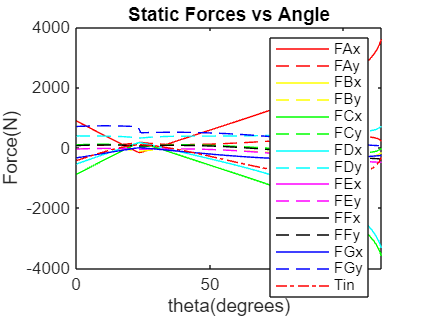


plot(x_theta,vectorForceA_PA(:,1),"r-"); hold on

plot(x_theta,vectorForceA_PA(:,2),"r--")

plot(x_theta,vectorForceB_PA(:,1),"y-")

plot(x_theta,vectorForceB_PA(:,2),"y--")

plot(x_theta,vectorForceC_PA(:,1),"g-")

plot(x_theta,vectorForceC_PA(:,2),"g--")

plot(x_theta,vectorForceD_PA(:,1),"c-")

plot(x_theta,vectorForceD_PA(:,2),"c--")

plot(x_theta,vectorForceE_PA(:,1),"m-")

plot(x_theta,vectorForceE_PA(:,2), "m--")

plot(x_theta,vectorForceF_PA(:,1),"k-")

plot(x_theta,vectorForceF_PA(:,2),"k--")

plot(x_theta,vectorForceG_PA(:,1),"b-")

plot(x_theta,vectorForceG_PA(:,2),"b--")

plot(x_theta,vectorTorquein_PA(:,3),"r-.")
legend("FAx","FAy","FBx","FBy","FCx","FCy","FDx","FDy","FEx","FEy","FFx","FFy","FGx","FGy","Tin")
title("Static Forces vs Angle")
xlabel('theta(degrees)')
ylabel('Force(N)')
hold off

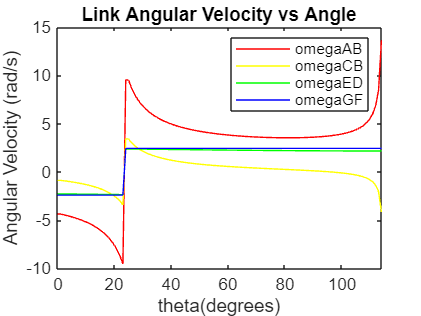




plot(x_theta,vector_omegaAB_PA(:,3),"r-"); hold on
plot(x_theta,vector_omegaCB_PA(:,3),"y-")
plot(x_theta,vector_omegaED_PA(:,3),"g-")
plot(x_theta,vector_omegaGF_PA(:,3),"b-")
legend("omegaAB","omegaCB","omegaED","omegaGF")
title("Link Angular Velocity vs Angle")
xlabel('theta(degrees)')
ylabel('Angular Velocity (rad/s)')
hold off

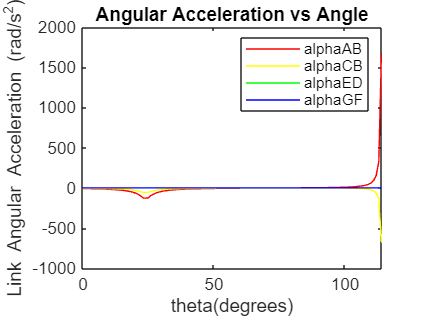


figure(3);
plot(x_theta,vector_alphaAB_PA(:,3),"r-"); hold on
plot(x_theta,vector_alphaCB_PA(:,3),"y-")
plot(x_theta,vector_alphaED_PA(:,3),"g-")
plot(x_theta,vector_alphaGF_PA(:,3),"b-")
legend("alphaAB","alphaCB","alphaED","alphaGF")
xlabel('theta(degrees)')
ylabel('Link Angular Acceleration (rad/s^2)')
title('Angular Acceleration vs Angle')

hold off

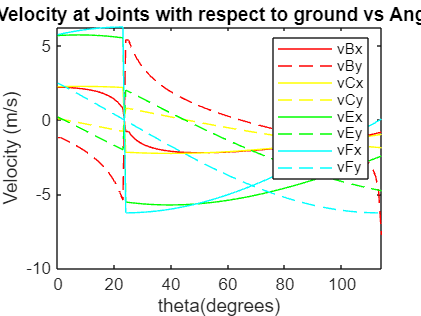



plot(x_theta,vectorvB_A_PA(:,1),"r-"); hold on

plot(x_theta,vectorvB_A_PA(:,2),"r--")

plot(x_theta,vectorvC_D_PA(:,1),"y-")

plot(x_theta,vectorvC_D_PA(:,2),"y--")

plot(x_theta,vectorvE_D_PA(:,1),"g-")

plot(x_theta,vectorvE_D_PA(:,2),"g--")

plot(x_theta,vectorvF_G_PA(:,1),"c-")

plot(x_theta,vectorvF_G_PA(:,2),"c--")
legend("vBx", "vBy","vCx", "vCy","vEx", "vEy","vFx", "vFy")
title("Velocity at Joints with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('Velocity (m/s)')
hold off

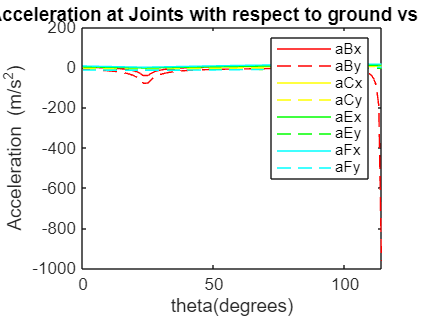


figure(5);
plot(x_theta,vectoraB_A_PA(:,1),"r-"); hold on

plot(x_theta,vectoraB_A_PA(:,2),"r--")

plot(x_theta,vectoraC_D_PA(:,1),"y-")

plot(x_theta,vectoraC_D_PA(:,2),"y--")

plot(x_theta,vectoraE_D_PA(:,1),"g-")

plot(x_theta,vectoraE_D_PA(:,2),"g--")

plot(x_theta,vectoraF_G_PA(:,1),"c-")

plot(x_theta,vectoraF_G_PA(:,2),"c--")
legend("aBx", "aBy","aCx", "aCy","aEx", "aEy","aFx", "aFy")
title("Acceleration at Joints with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('Acceleration (m/s^2)')
hold off

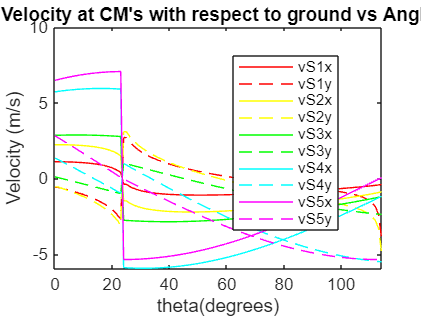



plot(x_theta,v_S1_A_PA(:,1),"r-"); hold on

plot(x_theta,v_S1_A_PA(:,2),"r--")

plot(x_theta,v_S2_A_PA(:,1),"y-")

plot(x_theta,v_S2_A_PA(:,2),"y--")

plot(x_theta,v_S3_D_PA(:,1),"g-")

plot(x_theta,v_S3_D_PA(:,2),"g--")

plot(x_theta,v_S4_G_PA(:,1),"c-")

plot(x_theta,v_S4_G_PA(:,2),"c--")

plot(x_theta,v_S5_G_PA(:,1),"m-")

plot(x_theta,v_S5_G_PA(:,2),"m--")
legend("vS1x", "vS1y","vS2x", "vS2y","vS3x", "vS3y","vS4x", "vS4y","vS5x", "vS5y")
title("Velocity at CM's with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('Velocity (m/s)')
hold off

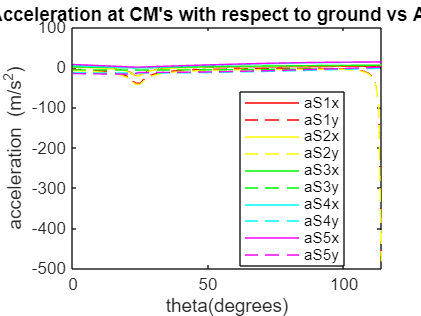


plot(x_theta,a_S1_A_PA(:,1),"r-"); hold on

plot(x_theta,a_S1_A_PA(:,2),"r--")

plot(x_theta,a_S2_A_PA(:,1),"y-")

plot(x_theta,a_S2_A_PA(:,2),"y--")

plot(x_theta,a_S3_D_PA(:,1),"g-")

plot(x_theta,a_S3_D_PA(:,2),"g--")

plot(x_theta,a_S4_G_PA(:,1),"c-")

plot(x_theta,a_S4_G_PA(:,2),"c--")

plot(x_theta,a_S5_G_PA(:,1),"m-")

plot(x_theta,a_S5_G_PA(:,2),"m--")
legend("aS1x", "aS1y","aS2x", "aS2y","aS3x", "aS3y","aS4x", "aS4y","aS5x", "aS5y")
title("Acceleration at CM's with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('acceleration (m/s^2)')
hold off

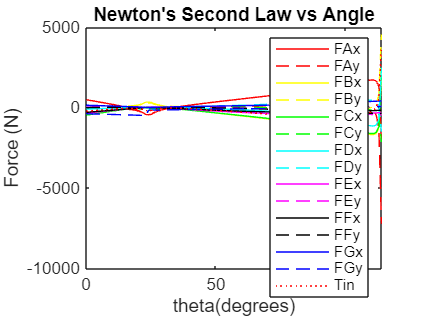


plot(x_theta,VectorNForceA_PA(:,1),"r-"); hold on

plot(x_theta,VectorNForceA_PA(:,2),"r--")

plot(x_theta,VectorNForceB_PA(:,1),"y-")

plot(x_theta,VectorNForceB_PA(:,2),"y--")

plot(x_theta,VectorNForceC_PA(:,1),"g-")

plot(x_theta,VectorNForceC_PA(:,2),"g--")

plot(x_theta,VectorNForceD_PA(:,1),"c-")

plot(x_theta,VectorNForceD_PA(:,2),"c--")

plot(x_theta,VectorNForceE_PA(:,1),"m-")

plot(x_theta,VectorNForceE_PA(:,2), "m--")

plot(x_theta,VectorNForceF_PA(:,1),"k-")

plot(x_theta,VectorNForceF_PA(:,2),"k--")

plot(x_theta,VectorNForceG_PA(:,1),"b-")

plot(x_theta,VectorNForceG_PA(:,2),"b--")

plot(x_theta,VectorNTorque_PA(:,3),"r:")
legend("FAx","FAy","FBx","FBy","FCx","FCy","FDx","FDy","FEx","FEy","FFx","FFy","FGx","FGy","Tin")
title("Newton's Second Law vs Angle")
xlabel('theta(degrees)')
ylabel('Force (N)')
hold off

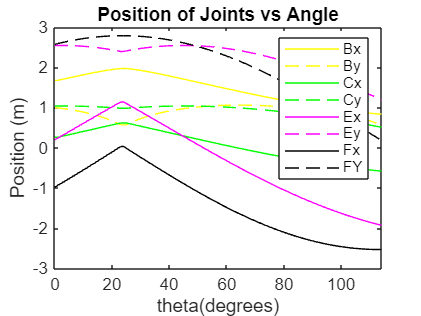


plot(x_theta,new_B_x(:,1),"y-"); hold on

plot(x_theta,new_B_y(:,1),"y--")

plot(x_theta,new_C_x(:,1),"g-")

plot(x_theta,new_C_y(:,1),"g--")

plot(x_theta,new_E_x(:,1),"m-")

plot(x_theta,new_E_y(:,1), "m--")

plot(x_theta,new_F_x(:,1),"k-")

plot(x_theta,new_F_y(:,1),"k--")
legend("Bx","By","Cx","Cy","Ex","Ey","Fx","FY")
title("Position of Joints vs Angle")
xlabel('theta(degrees)')
ylabel('Position (m)')
hold off

%This section reserved for table-making and data evaluation.
forcesmatrix(1,1:3)=vectorForceA_PA(1,1:3);
forcesmatrix(2,1:3)=vectorForceB_PA(1,1:3);
forcesmatrix(3,1:3)=vectorForceC_PA(1,1:3);
forcesmatrix(4,1:3)=vectorForceD_PA(1,1:3);
forcesmatrix(5,1:3)=vectorForceE_PA(1,1:3);
forcesmatrix(6,1:3)=vectorForceF_PA(1,1:3);
forcesmatrix(7,1:3)=vectorForceG_PA(1,1:3);
forcesmatrix(8,1:3)=vectorTorquein_PA(1,1:3);

PMKSmatrix(2,1:3)=[-879.34, -41.4752, 0];
PMKSmatrix(1,1:3)=[879.34, 97.6473, 0];
PMKSmatrix(3,1:3)=[-879.3403, 97.405, 0];
PMKSmatrix(4,1:3)=[-539.9257, -390.3279, 0];
PMKSmatrix(5,1:3)=[-339.4147, -48.9875, 0];
PMKSmatrix(6,1:3)=[-339.4147, 66.3193, 0];
PMKSmatrix(7,1:3)=[-339.4147, 700.6182, 0];
PMKSmatrix(8,1:3)=[0, 0, -425.2853];

forces_table=array2table(forcesmatrix, 'VariableNames',{'x','y','z'},'RowNames', {'FA','FB','FC','FD','FE','FF','FG','Tin',})

forces_table = 8×3 table
              x          y          z   
           _______    _______    _______

    FA      879.02     96.736          0
    FB     -879.02    -40.564          0
    FC     -879.02     98.316          0
    FD     -539.61     391.24          0
    FE     -339.41    -48.991          0
    FF     -339.41     66.316          0
    FG     -339.41     700.61          0
    Tin          0          0    -423.96


PMKSforces_table=array2table(PMKSmatrix, 'VariableNames',{'x','y','z'},'RowNames', {'FA','FB','FC','FD','FE','FF','FG','Tin',})

PMKSforces_table = 8×3 table
              x          y          z   
           _______    _______    _______

    FA      879.34     97.647          0
    FB     -879.34    -41.475          0
    FC     -879.34     97.405          0
    FD     -539.93    -390.33          0
    FE     -339.41    -48.987          0
    FF     -339.41     66.319          0
    FG     -339.41     700.62          0
    Tin          0          0    -425.29


%These sections reserved for table-making and data evaluation.
Nmatrix(1,1:3)=VectorNForceA_PA(1,1:3);
Nmatrix(2,1:3)=VectorNForceB_PA(1,1:3);
Nmatrix(3,1:3)=VectorNForceC_PA(1,1:3);
Nmatrix(4,1:3)=VectorNForceD_PA(1,1:3);
Nmatrix(5,1:3)=VectorNForceE_PA(1,1:3);
Nmatrix(6,1:3)=VectorNForceF_PA(1,1:3);
Nmatrix(7,1:3)=VectorNForceG_PA(1,1:3);
Nmatrix(8,1:3)=VectorNTorque_PA(1,1:3);

Nmatrix_table=array2table(Nmatrix, 'VariableNames',{'x','y','z'},'RowNames', {'FA','FB','FC','FD','FE','FF','FG','Tin',})

Nmatrix_table = 8×3 table
              x          y          z   
           _______    _______    _______

    FA      474.63     6.4887          0
    FB     -476.77     15.219          0
    FC     -477.88     32.651          0
    FD     -108.32     86.412          0
    FE     -349.58     28.902          0
    FF     -304.57    -13.867          0
    FG      136.34    -394.08          0
    Tin          0          0    -242.18



matrix_omega(1,1:3)=vector_omegaAB_PA(1,1:3);
matrix_omega(2,1:3)=vector_omegaCB_PA(1,1:3);
matrix_omega(3,1:3)=vector_omegaED_PA(1,1:3);
matrix_omega(4,1:3)=vector_omegaFE_PA(1,1:3);
matrix_omega(5,1:3)=vector_omegaGF_PA(1,1:3);

omegamatrix_table=array2table(matrix_omega, 'VariableNames',{'x','y','z'},'RowNames', {'wAB','wCB','wED','wFE','wGF'})

omegamatrix_table = 5×3 table
           x    y       z    
           _    _    ________

    wAB    0    0     -4.3717
    wCB    0    0    -0.88632
    wED    0    0     -2.2883
    wFE    0    0     -1.9496
    wGF    0    0     -2.4241


%Non PMKS
matrix_alpha(1,1:3)=vector_alphaAB_PA(1,1:3);
matrix_alpha(2,1:3)=vector_alphaCB_PA(1,1:3);
matrix_alpha(3,1:3)=vector_alphaED_PA(1,1:3);
matrix_alpha(4,1:3)=vector_alphaFE_PA(1,1:3);
matrix_alpha(5,1:3)=vector_alphaGF_PA(1,1:3);


alpha_table=array2table(matrix_alpha, 'VariableNames',{'x','y','z'},'RowNames', {'alphaAB','alphaCB','alphaED','alphaFE','alphaGF'})

alpha_table = 5×3 table
               x    y       z    
               _    _    ________

    alphaAB    0    0      -8.856
    alphaCB    0    0     -4.9152
    alphaED    0    0    -0.45723
    alphaFE    0    0     0.71543
    alphaGF    0    0           0




matrix_v(1,1:3)=vectorvB_A_PA(1,1:3);
matrix_v(2,1:3)=vectorvC_D_PA(1,1:3);
matrix_v(3,1:3)=vectorvE_D_PA(1,1:3);
matrix_v(4,1:3)=vectorvF_G_PA(1,1:3);
matrix_v=round(matrix_v,4);
vmatrix_table=array2table(matrix_v, 'VariableNames',{'x','y','z'},'RowNames', {'vBA','vCD','vED','vFG'})

vmatrix_table = 4×3 table
             x          y       z
           ______    _______    _

    vBA    2.2015    -1.1913    0
    vCD    2.2427    0.0628     0
    vED    5.6864    0.2059     0
    vFG    5.7449    2.4967     0



matrix_a(1,1:3)=vectoraB_A_PA(1,1:3);
matrix_a(2,1:3)=vectoraC_D_PA(1,1:3);
matrix_a(3,1:3)=vectoraE_D_PA(1,1:3);
matrix_a(4,1:3)=vectoraF_G_PA(1,1:3);
matrix_a=round(matrix_a,4);
amatrix_table=array2table(matrix_a, 'VariableNames',{'x','y','z'},'RowNames', {'aBA','aCD','aED','aFG'})

amatrix_table = 4×3 table
              x          y        z
           _______    ________    _

    aBA    -0.7483    -12.0378    0
    aCD    0.5917     -5.1196     0
    aED    1.6073     -12.9713    0
    aFG    6.0522     -13.926     0




matrix_as(1,1:3)=a_S1_A_PA(1,1:3);
matrix_as(2,1:3)=a_S2_A_PA(1,1:3);
matrix_as(3,1:3)=a_S3_D_PA(1,1:3);
matrix_as(4,1:3)=a_S4_G_PA(1,1:3);
matrix_as(5,1:3)=a_S5_G_PA(1,1:3);
matrix_as=round(matrix_as,4);
asmatrix_table=array2table(matrix_as, 'VariableNames',{'x','y','z'},'RowNames', {'aS1A','aS2A','aS3D','aS4G','aS5G'})

asmatrix_table = 5×3 table
               x          y        z
            _______    ________    _

    aS1A    -0.3741    -6.0189     0
    aS2A    -0.0783    -8.5787     0
    aS3D    0.8037     -6.4857     0
    aS4G    3.8298     -13.4486    0
    aS5G    6.819      -15.6904    0


%PMKS Tables
%PMKS joint velocity
matrix_v_PMKS(1,1:3)=[2.2029, -1.1778, 0];
matrix_v_PMKS(2,1:3)=[2.2426, 0.0682, 0];
matrix_v_PMKS(3,1:3)=[5.6866, 0.2048, 0];
matrix_v_PMKS(4,1:3)=[5.7455, 2.4956, 0];
PMKSvmatrix_table=array2table(matrix_v_PMKS, 'VariableNames',{'x','y','z'},'RowNames', {'vBA','vCD','vED','vFG'})

PMKSvmatrix_table = 4×3 table
             x          y       z
           ______    _______    _

    vBA    2.2029    -1.1778    0
    vCD    2.2426     0.0682    0
    vED    5.6866     0.2048    0
    vFG    5.7455     2.4956    0



%PMKS joint acceleration
matrix_a_PMKS(1,1:3)=[-.7147, -11.981, 0];
matrix_a_PMKS(2,1:3)=[.6042, -5.113, 0];
matrix_a_PMKS(3,1:3)=[1.605, -12.9722, 0];
matrix_a_PMKS(4,1:3)=[6.0494, -13.9274, 0];
amatrix_table_PMKS=array2table(matrix_a_PMKS, 'VariableNames',{'x','y','z'},'RowNames', {'aBA','aCD','aED','aFG'})

amatrix_table_PMKS = 4×3 table
              x          y       z
           _______    _______    _

    aBA    -0.7147    -11.981    0
    aCD     0.6042     -5.113    0
    aED      1.605    -12.972    0
    aFG     6.0494    -13.927    0



%PMKS omega link angular velocity
matrix_omega_PMKS(1,1:3)=[0, 0, -4.363];
matrix_omega_PMKS(2,1:3)=[0, 0, -.8813];
matrix_omega_PMKS(3,1:3)=[0, 0, -2.2884];
matrix_omega_PMKS(4,1:3)=[0, 0, -1.9496];
matrix_omega_PMKS(5,1:3)=[0, 0, -2.4241];

PMKS_omegamatrix_table=array2table(matrix_omega_PMKS, 'VariableNames',{'x','y','z'},'RowNames', {'wAB','wCB','wED','wFE','wGF'})

PMKS_omegamatrix_table = 5×3 table
           x    y       z   
           _    _    _______

    wAB    0    0     -4.363
    wCB    0    0    -0.8813
    wED    0    0    -2.2884
    wFE    0    0    -1.9496
    wGF    0    0    -2.4241



%PMKS alpha link angular acceleration
matrix_alpha_PMKS(1,1:3)=[0, 0, -8.7713];
matrix_alpha_PMKS(2,1:3)=[0, 0, -4.8747];
matrix_alpha_PMKS(3,1:3)=[0, 0, -.4573];
matrix_alpha_PMKS(4,1:3)=[0, 0, -.7152];
matrix_alpha_PMKS(5,1:3)=[0, 0, 0];


PMKS_alpha_table=array2table(matrix_alpha_PMKS, 'VariableNames',{'x','y','z'},'RowNames', {'alphaAB','alphaCB','alphaED','alphaFE','alphaGF'})

PMKS_alpha_table = 5×3 table
               x    y       z   
               _    _    _______

    alphaAB    0    0    -8.7713
    alphaCB    0    0    -4.8747
    alphaED    0    0    -0.4573
    alphaFE    0    0    -0.7152
    alphaGF    0    0          0



%PMKS Acceleration at Mass Centers
matrix_as_PMKS(1,1:3)=[-.4813, -5.9824, 0];
matrix_as_PMKS(2,1:3)=[-.0561, -8.4959, 0];
matrix_as_PMKS(3,1:3)=[-.6588, -6.5022, 0];
matrix_as_PMKS(4,1:3)=[3.8244, -13.4498, 0];
matrix_as_PMKS(5,1:3)=[6.8112, -15.6935, 0];
matrix_as_PMKS=round(matrix_as_PMKS,4);
asmatrix_table_PMKS=array2table(matrix_as_PMKS, 'VariableNames',{'x','y','z'},'RowNames', {'aS1A','aS2A','aS3D','aS4G','aS5G'})

asmatrix_table_PMKS = 5×3 table
               x          y       z
            _______    _______    _

    aS1A    -0.4813    -5.9824    0
    aS2A    -0.0561    -8.4959    0
    aS3D    -0.6588    -6.5022    0
    aS4G     3.8244     -13.45    0
    aS5G     6.8112    -15.694    0
